# MATLAB Final Exam by Cole Bardin     Setion 62

## Part A

## Question 1

clc, clear
A = [10;-20;10;20;-40;20];
B = [50;40;30;20;10;-150];
C = [10;10;10;20;30;30];
D = [10;10;10;10;6;4];

ANorm = norm(A)

ANorm = 54.7723

BNorm = norm(B)

BNorm = 167.3320

CNorm = norm(C)

CNorm = 50

DNorm = norm(D)

DNorm = 21.2603

## Quesion 2

clc, clear
A = [6;0;6;0];
B = [12;0;0;0];
C = [6;6;6;6];
D = [-12;12;-12;12];

Anorms = [norm(A,1);norm(A);norm(A,Inf)]

Anorms =    12.0000
    8.4853
    6.0000


Bnorms = [norm(B,1);norm(B);norm(B,Inf)]

Bnorms =     12
    12
    12


Cnorms = [norm(C,1);norm(C);norm(C,Inf)]

Cnorms =     24
    12
     6


Dnorms = [norm(D,1);norm(D);norm(D,Inf)]

Dnorms =     48
    24
    12


## Question 3

clc, clear
A = pascal(5);
B = pascal(5,1);
C = pascal(5,2);

A2 = A*A

A2 =            5          15          35          70         126
          15          55         140         294         546
          35         140         371         798        1506
          70         294         798        1742        3321
         126         546        1506        3321        6376


B2 = B*B

B2 =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


C2 = C*C

C2 =      0     0     0     0     1
     0     0     0    -1    -4
     0     0     1     3     6
     0    -1    -2    -3    -4
     1     1     1     1     1


## Question 4

clc, clear
A = [4,3,2,1;5,4,3,2];
AI = [A, eye(2)]

AI =      4     3     2     1     1     0
     5     4     3     2     0     1


AIR = rref(AI)

AIR =      1     0    -1    -2     4    -3
     0     1     2     3    -5     4



R = AIR(:,5:end)

R =      4    -3
    -5     4


B = AIR(:,1:4)

B =      1     0    -1    -2
     0     1     2     3



if isequal(B, R*A)
    fprintf("Verified that B = R*A\n")
end

Verified that B = R*A


## Question 5

clc, clear
disp("Question 5:")

Question 5:


C = [-1,2,2;2,2,-1;2,-1,2];
A = [C;C];

V1 = [1;1;1;1;1;1];
V2 = [1;2;3;1;2;3];
V3 = [6;6;6;0;0;0;];
V4 = [1;2;3;-1;-2;-3];

V1_res = A'*V1

V1_res =      6
     6
     6


V2_res = A'*V2

V2_res =     18
     6
    12


V3_res = A'*V3

V3_res =     18
    18
    18


V4_res = A'*V4

V4_res =      0
     0
     0



% Question 6
disp("Question 6:")

Question 6:


b = [14;5;11;14;5;11];
AM = [A,b];
RAM = rref(AM)

RAM =      1     0     0     2
     0     1     0     3
     0     0     1     5
     0     0     0     0
     0     0     0     0
     0     0     0     0



% Question 7
disp("Question 7:")

Question 7:


x = inv(A'*A)*A'*b

x =     2.0000
    3.0000
    5.0000


## Question 8

clc, clear
A = toeplitz( [1 0 0 0 0]', [1 2 3 4 5]);
V = [1;1;1;1;1];

VtAtAV = V'*A'*A*V

VtAtAV = 371

## Questions 9-10

clc, clear
A = toeplitz( [1 0 0 0 0]', [1 2 3 4 5]);

AI = [A, eye(5)]

AI =      1     2     3     4     5     1     0     0     0     0
     0     1     2     3     4     0     1     0     0     0
     0     0     1     2     3     0     0     1     0     0
     0     0     0     1     2     0     0     0     1     0
     0     0     0     0     1     0     0     0     0     1


AIR = rref(AI)

AIR =      1     0     0     0     0     1    -2     1     0     0
     0     1     0     0     0     0     1    -2     1     0
     0     0     1     0     0     0     0     1    -2     1
     0     0     0     1     0     0     0     0     1    -2
     0     0     0     0     1     0     0     0     0     1


Ainv = AIR(:,6:end)

Ainv =      1    -2     1     0     0
     0     1    -2     1     0
     0     0     1    -2     1
     0     0     0     1    -2
     0     0     0     0     1


## Part B

## Question 1

clc, clear
A = sym(hadamard(8));
b = [20;-4;-8;0;0;0;0;0];

disp("Question 1:")

Question 1:


detA = det(A)

$$detA = 4096$$


% Question 2
disp("Question 2:")

Question 2:


A8 = A;
A8(:,8) = b

$$A8 = \left(\begin{array}{cccccccc} 1 & 1 & 1 & 1 & 1 & 1 & 1 & 20\\ 1 & -1 & 1 & -1 & 1 & -1 & 1 & -4\\ 1 & 1 & -1 & -1 & 1 & 1 & -1 & -8\\ 1 & -1 & -1 & 1 & 1 & -1 & -1 & 0\\ 1 & 1 & 1 & 1 & -1 & -1 & -1 & 0\\ 1 & -1 & 1 & -1 & -1 & 1 & -1 & 0\\ 1 & 1 & -1 & -1 & -1 & -1 & 1 & 0\\ 1 & -1 & -1 & 1 & -1 & 1 & 1 & 0 \end{array}\right)$$


% Question 3
disp("Question 3:")

Question 3:


x8 = det(A8)/det(A)

$$x8 = 4$$


% Questions 4-5
disp("Question 4:")

Question 4:


N = size(A,2);
x = zeros(N,1);
for i= 1:N
    Ai = A;
    Ai(:,i) = b;
    x(i) = det(Ai)/det(A);
end
x

x =      1
     2
     3
     4
     1
     2
     3
     4


## Part C

## Question 1

clc, clear
M = [1,0,3,0;0,2,0,4;1,2,3,4;-1,2,-3,4];
A = [M, M*M];
disp("Question 1:")

Question 1:


Ared = rref(A)

Ared =      1     0     3     0     4     6    12    12
     0     1     0     2    -2     6    -6    12
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0



% Question 2
disp("Question 2:")

Question 2:


R = Ared(1:2,:)

R =      1     0     3     0     4     6    12    12
     0     1     0     2    -2     6    -6    12



% Question 3
disp("Question 3:")

Question 3:


N = null(A,'r')

N =     -3     0    -4    -6   -12   -12
     0    -2     2    -6     6   -12
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



% Question 4
disp("Question 4:")

Question 4:


RN = R*N

RN =      0     0     0     0     0     0
     0     0     0     0     0     0



% Question 5
disp("Question 5:")

Question 5:


AtA = null(A'*A,'r')

AtA =     -3     0    -4    -6   -12   -12
     0    -2     2    -6     6   -12
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


AAt = null(A*A','r')

AAt =     -1     1
    -1    -1
     1     0
     0     1


AAtA = null(A*A'*A,'r')

AAtA =     -3     0    -4    -6   -12   -12
     0    -2     2    -6     6   -12
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


AtAAtA = null(A'*A*A'*A,'r')

AtAAtA =     -3     0    -4    -6   -12   -12
     0    -2     2    -6     6   -12
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


## Part D

## Question 1

clc, clear, close all
format short
clear, clc, close all
% The years the Olympics were held.
x = [1900 1904 1908 1912 1920 1924 1928 1932 1936 1948 1952 1956 1960 1964 1968 1972 1976 1980 1984 1988 1992 1996 2000]';
% Winning time in seconds.
y = [246.2 245.4 243.4 236.8 241.8 233.6 233.2 231.2 227.8 229.8 225.2 221.2 215.6 218.1 214.9 216.3 219.17 218.4 212.53 215.96 220.12 215.78 212.07]';

N = numel(x);
D = [ones(N,1), x];

disp("Question 1:")

Question 1:


DtD = D'*D

DtD =           23       44900
       44900    87674608



% Question 2
disp("Question 2:")

Question 2:


b = inv(DtD)*D'*y

b =   874.4631
   -0.3323



% Question 3
disp("Question 3:")

Question 3:


yest = D*b;
e = y - yest;
RMSE = sqrt( (e'*e)/N )

RMSE = 3.6711

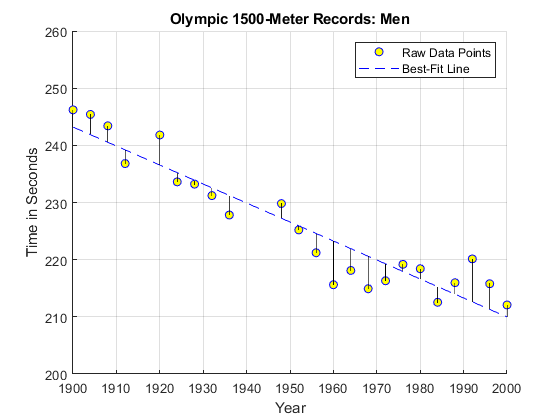


% Questions 4-5
hold on
grid on
plot(x,y,'bo','MarkerFaceColor','y')
plot(x, yest, 'b--')
title("Olympic 1500-Meter Records: Men")
xlabel("Year")
ylabel("Time in Seconds")
axis([1900,2000,200,260])

for i=1:N
    plot([x(i), x(i)], [y(i), yest(i)], 'k')
end

legend(["Raw Data Points", "Best-Fit Line"])